# Create Rotational Transformation Matrix from Axis-Angle Representation of Rotation in Space

## obvious solution:

% https://de.mathworks.com/help/robotics/ref/axang2rotm.html

Problem is, doesn't accept syms data type

Definition

syms C ga B f_WSTrad phi
% C = f_WSTrad * B
phi = -C+ga;

Rotation of angle phi around z-axis

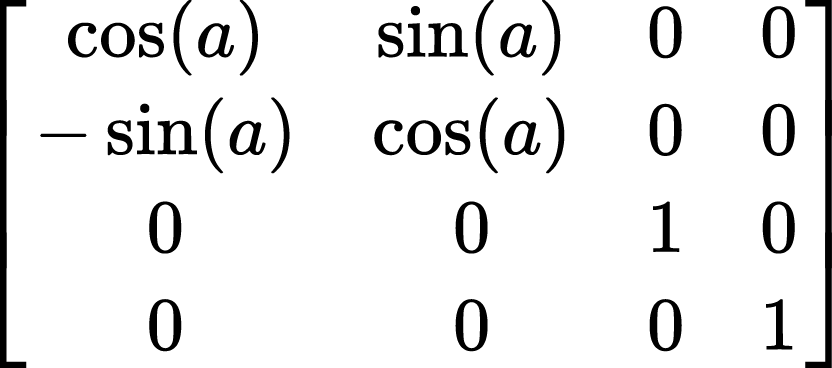

### Hardcode

R_Cga= [cos(phi) -sin(phi) 0 0; sin(phi) cos(phi) 0 0; 0 0 1 0; 0 0 0 1]

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0 & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Using a rotated vector

kvec = [0;0;1];     % unit vector of rotation axis
vvec = [1;0;0];     % unit vector of direction in R^3
vrot = vvec*cos(phi) + (cross(kvec,vvec))*sin(phi) + kvec*dot(kvec,vvec)*(1-cos(phi))

$$vrot = \left(\begin{array}{c} \cos\left(C-\mathrm{ga}\right)\\ -\sin\left(C-\mathrm{ga}\right)\\ 0 \end{array}\right)$$

R_Cga = vec2rot(vrot,[0,0,1])

$$R\_Cga = \begin{array}{l} \left(\begin{array}{cccc} 1-\frac{{\cos\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{4}\,\left(\sigma_{6}+\sigma_{5}\right)} & \sigma_{1} & -\sigma_{3} & 0\\ \sigma_{1} & 1-\frac{{\sin\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{4}\,\left(\sigma_{6}+\sigma_{5}\right)} & \sigma_{2} & 0\\ \sigma_{3} & -\sigma_{2} & 1-\frac{\frac{{\cos\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{6}+\sigma_{5}}+\frac{{\sin\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{6}+\sigma_{5}}}{\sigma_{4}} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(C-\mathrm{ga}\right)\,\sin\left(C-\mathrm{ga}\right)}{\sigma_{4}\,\left(\sigma_{6}+\sigma_{5}\right)}\\ \sigma_{2}=\frac{\sin\left(C-\mathrm{ga}\right)}{\sqrt{\sigma_{6}+\sigma_{5}}}\\ \sigma_{3}=\frac{\cos\left(C-\mathrm{ga}\right)}{\sqrt{\sigma_{6}+\sigma_{5}}}\\ \sigma_{4}=\frac{\sigma_{6}}{\sigma_{6}+\sigma_{5}}+\frac{\sigma_{5}}{\sigma_{6}+\sigma_{5}}\\ \sigma_{5}={\left|\sin\left(C-\mathrm{ga}\right)\right|}^{2}\\ \sigma_{6}={\left|\cos\left(C-\mathrm{ga}\right)\right|}^{2} \end{array}$$

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \frac{\sigma_{5}+\sigma_{4}-{\cos\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{5}+\sigma_{4}} & \sigma_{1} & -\sigma_{3} & 0\\ \sigma_{1} & \frac{\sigma_{5}+\sigma_{4}+{\cos\left(C-\mathrm{ga}\right)}^{2}-1}{\sigma_{5}+\sigma_{4}} & \sigma_{2} & 0\\ \sigma_{3} & -\sigma_{2} & \frac{\sigma_{5}+\sigma_{4}-1}{\sigma_{5}+\sigma_{4}} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(2\,C-2\,\mathrm{ga}\right)}{2\,\left(\sigma_{5}+\sigma_{4}\right)}\\ \sigma_{2}=\frac{\sin\left(C-\mathrm{ga}\right)}{\sqrt{\sigma_{5}+\sigma_{4}}}\\ \sigma_{3}=\frac{\cos\left(C-\mathrm{ga}\right)}{\sqrt{\sigma_{5}+\sigma_{4}}}\\ \sigma_{4}={\left|\sin\left(C-\mathrm{ga}\right)\right|}^{2}\\ \sigma_{5}={\left|\cos\left(C-\mathrm{ga}\right)\right|}^{2} \end{array}$$

### Using a dedicated function

R_Cga = axang2rtm([0,0,1],phi)

$$R\_Cga = \left(\begin{array}{ccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

function RTM = axang2rtm(ax,ang)

Formula found [here](https://en.wikipedia.org/wiki/Rotation_matrix#Rotation_matrix_from_axis_and_angle):

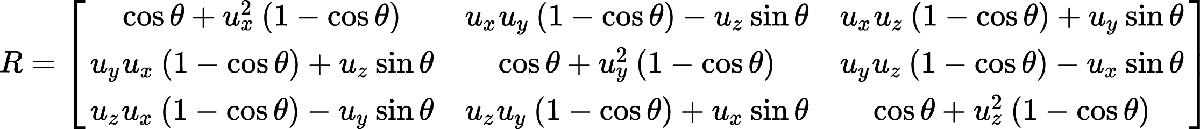

RTM = [cos(ang) + ax(1)^2*(1-cos(ang)),          ax(1)*ax(2)*(1-cos(ang))-ax(3)*sin(ang), ax(1)*ax(3)*(1-cos(ang)) + ax(2)*sin(ang);...
       ax(2)*ax(3)*(1-cos(ang))+ ax(3)*sin(ang), cos(ang) + ax(2)^2*(1-cos(ang)),         ax(2)*ax(3)*(1-cos(ang)) - ax(1)*sin(ang);...
       ax(3)*ax(1)*(1-cos(ang))-ax(2)*sin(ang),  ax(3)*ax(2)*(1-cos(ang))+ax(1)*sin(ang), cos(ang)+ ax(3)^2*(1-cos(ang))];
end